clear;
clc;

## Objective

energy_obj = @(x) x(2)^2 + x(3)^2;

## Constraints

LB = [0;-inf;-inf]; %Lower Bounds
UB = [inf;inf;inf]; %Upper Bounds

X0 = [1;2;3]; %Initial Condition

A = []; %No linear inequality constraints
B = [];

Aeq = []; %No linear equality constraints
Beq = [];

options = optimoptions('fmincon',...
                       'Algorithm', 'sqp',...
                       'Display', 'iter-detailed',...
                       'MaxFunctionEvaluations', 100000,...
                       'MaxIterations', 2000,...
                       'FunctionTolerance', 1e-10);

cannon_target = [8,3];

## Solve NLP

[X, Cost] = fmincon(@(x) energy_obj(x), X0, A, B, Aeq, Beq, LB, UB,...
            @(x) single_shooting_constraints(x, cannon_target), options);

 Iter  Func-count            Fval   Feasibility   Step Length       Norm of   First-order  
                                                                       step    optimality
    0           4    1.300000e+01     6.000e+00     1.000e+00     0.000e+00     6.000e+00  
    1          11    2.802005e+01     4.883e+00     3.430e-01     2.841e+00     1.476e+01  
    2          16    1.251257e+02     9.296e-01     7.000e-01     6.921e+00     6.578e+01  
    3          20    1.105800e+02     1.859e-01     1.000e+00     6.913e-01     4.904e+01  
    4          24    1.129947e+02     1.805e-02     1.000e+00     4.521e-01     1.136e+00  
    5          28    1.131311e+02     1.211e-05     1.000e+00     6.786e-03     9.691e-03  
    6          32    1.131312e+02     7.776e-09     1.000e+00     2.272e-04     1.509e-04  
    7          36    1.131312e+02     5.421e-12     1.000e+00     6.164e-06     1.747e-07  

Optimization completed: The relative 

disp(X)

    1.3205
    6.0584
    8.7423



disp(0.5*0.3*Cost) %Energy for cannon ball with mass 300 grams

   16.9697



## Plot

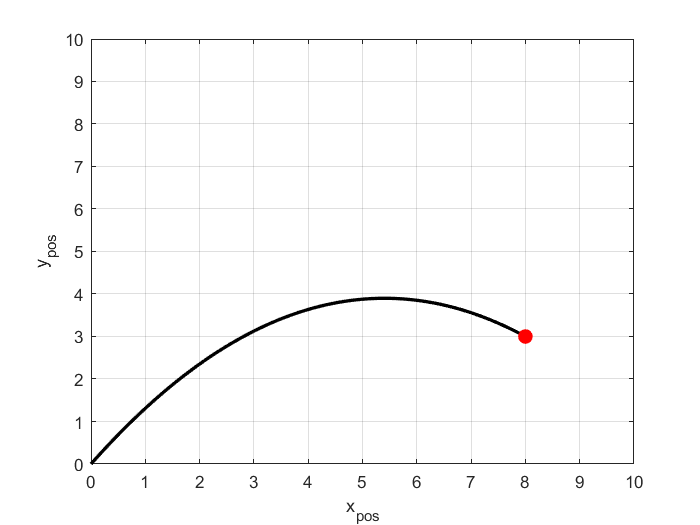

time = 0:X(1)/100:X(1);
x = X(2)*time;
y = X(3)*time - 0.5*9.8*time.^2;

figure(1);
plot(x,y,'k',"LineWidth",2);
xlabel('x_{pos}');
ylabel('y_{pos}');
xlim([0 10]);
ylim([0 10]);

hold on;
grid on;

plot(cannon_target(1), cannon_target(2), 'r.', 'MarkerSize', 30);